# Carhart 4 Factor Model

See Fama and French, 1993, "Common Risk Factors in the Returns on Stocks and Bonds," *Journal of Financial Economics*

MC = "Market Cap"

PB = "Price/Book"

*Small Stocks = MC <= median(MC)*

*Large Stocks = MC > median(MC)*

*Value Stocks = PB > prctile(PB,70%)*

*Neutral Stocks = PB >= prctile(PB,30%) & PB <= prctile(PB,70%)*

*Growth Stocks = PB <= prctile(PB,30%)*

**                              | Median Market Value of Equity (**Market Capitalization**) |**

                                                        Small Value      |     Big Value

*70th Percentile B/M (Price/Book)*** -----------------------------------------------**

                                                        Small Neutral    |     Big Neutral

*30th Percentile B/M (Price/Book)*** -----------------------------------------------**

                                                        Small Growth    |     Big Growth

**The Fama/French factors are constructed using the 6 value-weight portfolios formed on size and book-to-market.**

***[Factor #1: ****Market****] ****ri = rf + Beta*(rm - rf)*

SMB (Small Minus Big) is the average return on the three small portfolios minus the average return on the three big portfolios,

***[Factor #2: ****Size****] SMB**** = 1/3 (Small Value + Small Neutral + Small Growth) - 1/3 (Big Value + Big Neutral + Big Growth). *

HML (High Minus Low) is the average return on the two value portfolios minus the average return on the two growth portfolios,

***[Factor #3: ****Value vs. Growth****] HML**** =1/2 (Small Value + Big Value) - 1/2 (Small Growth + Big Growth).*

Rm-Rf, the excess return on the market, value-weight return of all CRSP firms incorporated in the US and listed on the NYSE, AMEX, or NASDAQ that have a CRSP share code of 10 or 11 at the beginning of month t, good shares and price data at the beginning of t, and good return data for t minus the one-month Treasury bill rate (from Ibbotson Associates).

***[Factor #4:**** Momentum****]*** ***UMD = ****Up-Minus-Down = Top 50% of highest performing stocks in the last 12 months - Bottom 50% of lowest performing stocks in the last 12 months*

***Good Data reference:***

- [https://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html](https://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html)

- [https://finance.yahoo.com/quote](https://finance.yahoo.com/quote)

**Columbia University - Machine Learning for Enterprise Risk Management**                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 [malphons@mathworks.com](http://malphons@mathworks.com) **|** [https://www.linkedin.com/in/marshallalphonso](https://www.linkedin.com/in/marshallalphonso)

## Load in Equity Data

load AllEquityData.mat
[Prices,Returns,FinData] = cleanPricesReturnsFinData(Prices,Returns,FinData);

Missing data detected, removing the following tickers
-----------------------------------------------------
IPHS


## Construct Carhart 4 Factor Model

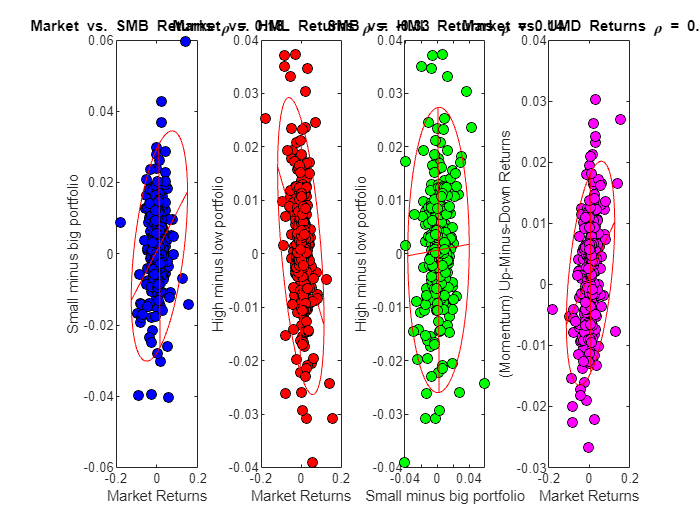

Ports = constructFF4Ports(FinData,Prices,Returns);
plot4FactorReturns(Ports.returnsMarket,Ports.returnsSMB,Ports.returnsHML,Ports.returnsUMD)

## Beta to the 4 Factors

secReturns = E.largeReturns.ADM;
secReturnsMinusRf = secReturns-LIBOR.Rates(2:end);
[MdlFF4,T] = fitFF4FactorModel(LIBOR,Ports.returnsMarket,Ports.returnsSMB,Ports.returnsHML,Ports.returnsUMD,secReturns);
disp(MdlFF4)

Linear regression model:
    RiMinusRf ~ 1 + Rsmb + Rhml + Rumd + RmMinusRf

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   ___________    _________    ________    __________

    (Intercept)    -0.00081319    0.0023104    -0.35198       0.72512
    Rsmb              -0.31178      0.20325      -1.534       0.12614
    Rhml              -0.47655      0.20374      -2.339      0.020028
    Rumd              -0.17605      0.28756    -0.61223       0.54087
    RmMinusRf           0.8195     0.068719      11.925    7.2126e-27


Number of observations: 290, Error degrees of freedom: 285
Root Mean Squared Error: 0.0375
R-squared: 0.406,  Adjusted R-Squared: 0.397
F-statistic vs. constant model: 48.6, p-value = 3

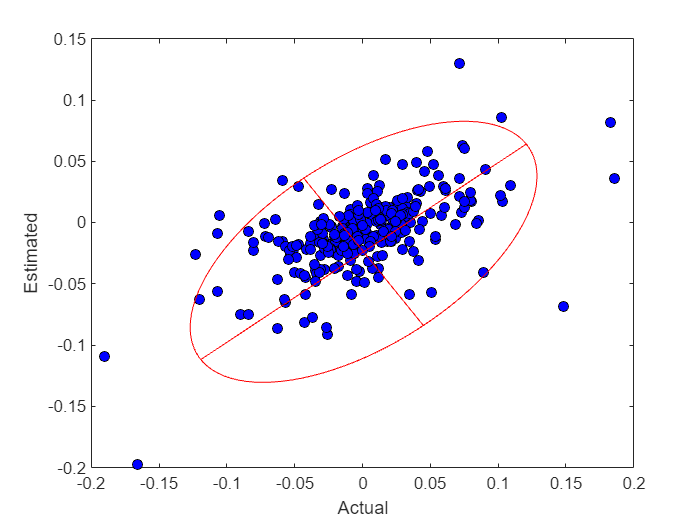

secReturnsHAT = predict(MdlFF4,T);

figure
plot(secReturns,secReturnsHAT,'ko','MarkerFaceColor','blue')
fit_ellipse(secReturns,secReturnsHAT,gca);
xlabel('Actual'); ylabel('Estimated')

## Study the error term

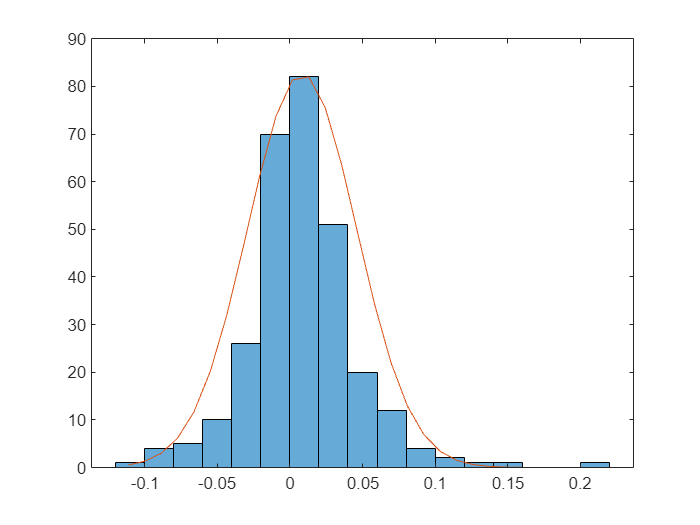

error         = secReturns - secReturnsHAT;
pd            = fitdist(error,'Normal');
erX           = linspace(min(error),max(error),30);
pdfError      = pdf(pd,erX);

figure
h = histogram(error); hold on; plot(erX,max(h.Values)*pdfError/max(pdfError))

## Beta to the 4 Factors over time

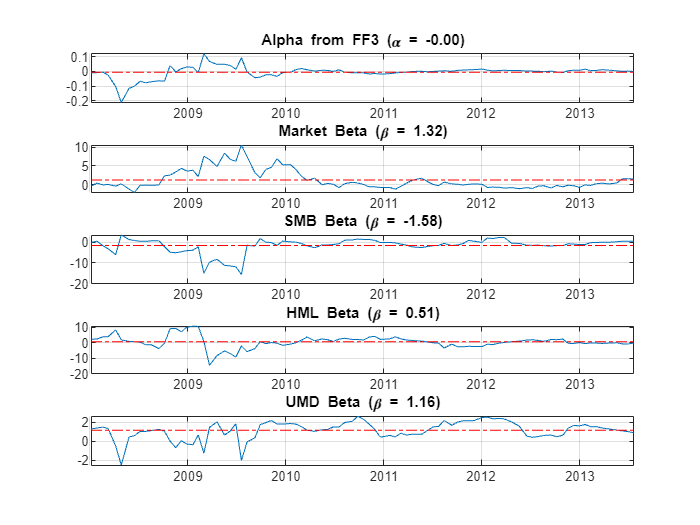

StepSize   = 3;
WindowSize = 20;
fitRolling4FactorModel(E.largeReturns.AIG,StepSize,WindowSize,Dates,LIBOR,Ports.returnsMarket,Ports.returnsSMB,Ports.returnsHML,Ports.returnsUMD);